# Minimum Airspeed for Takeoff vs Altitude

(Adapted from AE2440, AY24Q4, courtesy of Prof. Dobrokodov.)

Topics:

- Functions

- Logicals - using `find`

- Vector element-wise arithmetic

- 2D line ploting

In this task, you need to explore and code in MATLAB the dependency of the minimum ground speed ($V_{min}
$) for takeoff of an aircraft on the runway altitude ($h_{runway}$). 

## Models:

Here is a mathematical model for the relationship:


$$V_{\text{min}} = \sqrt{\frac{ 2 M g}{\rho(h_{runway}) \, S  \,C_L}}$$


where the air density ($\rho$) is modeled with the exponential

$\rho(h) = \rho_0 e^{-\frac{h}{H}}$.

(This is very simple model.  You don't need to understand the model to complete the assignment, but having some physical context will help in debugging the solution.)

Consider the nominal values for an F/A-18 Super Hornet.

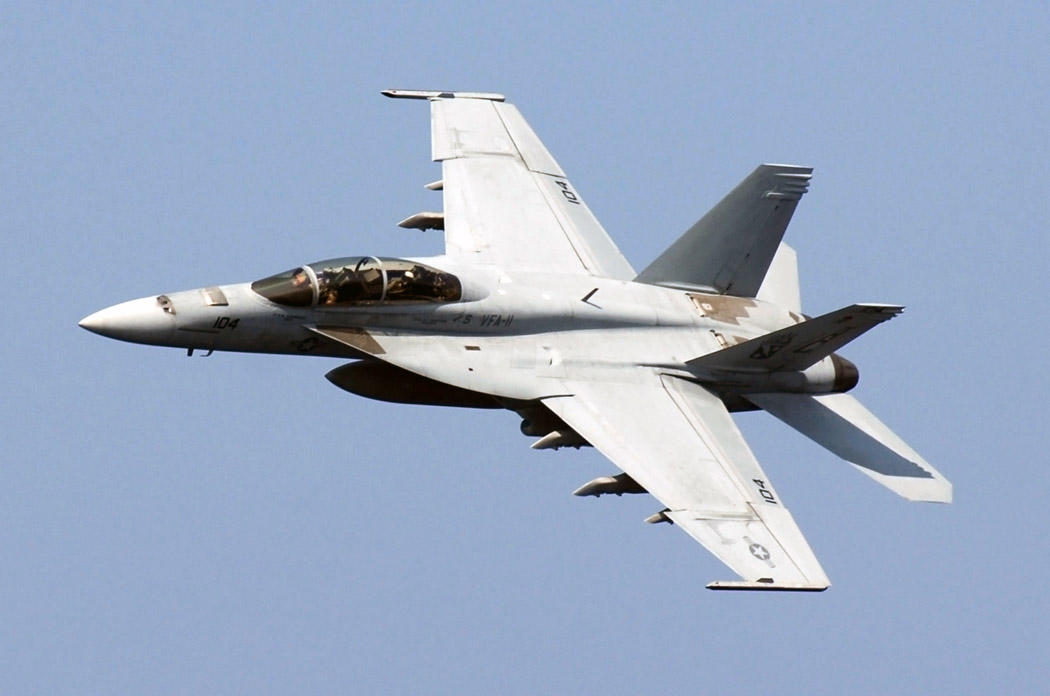

The constant coefficients are as follows:

- Lift coefficient - $C_L = 1.75$ dimensionless

- Effective wing surface area - $S = 37.2 \ m^2$ 

- Idealized altitude scale - $H = 8500 \ m$

- 
$$\rho_0=1.225\frac{kg}{m^3}$$


- Acceleration of gravity - $g = 9.81 \ m/s^2$

Consider two configurations for the aircraft mass

- Empty - $M = 14500 \ kg$

- Max Takeoff Weight - $M = 30000 \ kg
$

Exercises are described in the sections below

## Local functions

Write a two local functions to calculate the relationship based on the prototypes below.

Takeoff speed as a function fo altitude and aircraft mass.  Here is a prototype that you can use:

% Your code here.       

Local function called as a sub-routine of the `takeoff_speed` function.  Again, with a prototype for you to use:

% Your code here.       

Follwing incremental development, let's try this out before moving ahead.  Recall that 1 m/s ~ 2 kts.  Does it work for scalar input?

% Your code here.       

How about for vector input?  We expect that as altitude increases, density decreases, so would need more ground speed to takeoff.

% Your code here.       

## Plot using vectors.

Create a *well-documented* plot of the $V_{min}(h_{runway})$ for the two configurations (Empty and Max Takeoff Weight) as altitude varies 0 and 5000 m with step size of 100 m.  Use different line types, colors and line widths for the two line plots.  Inlcude a legend in a place that it doesn't obscure the information.  Include labels (with units) on the axes.

Make sure the visualization of the relationship matches your intuition; at higher altitude, would an aircraft need to go faster or slower (relative to ground, with no wind) to achieve the necessary lift for takeoff?  With more mass/weight does an aicraft need more or less ground speed to take off?

% Your code here.       

## Using `find` to locate functional pairs.

We want to answer the following question:

- Given the model above for two cases (empty and full)

- Consider the empty case, where $M = 14,500 \, kg$, and the maximum speed of the aircraft is $V_{\text{max}} = 70 m/s$.  What is the highest altitude runway that our plane can safely takeoff?

- Consider the full case, where $M = 30,000 \, kg$, and the maximum speed of the aircraft is $V_{\text{max}} = 90 \, m/s
$.  What this the hightest altitude run way that our plane can safely takeoff?

One way to accomplish this is to do the following

- Find the *index *of the* first *element of the velocity vector (the vector used to create the graph above) for which the element of the velocity vector is greater-than-or-equal to $V_{\text{max}}
$.

- Find the value of the altitude vector that corresponsd to the *index* we found in part 1.  This is the maximum altitude we are looking for.

Find the two values for maximum altitude desribed in the problem statement.

% Your code here.       

ans = 59.7276

Annotate the figure to overlay markers (squares) to illustrate the location of the altitude/velocity pairs and verify the points are along the original curves.

ans =    59.7276   80.1509


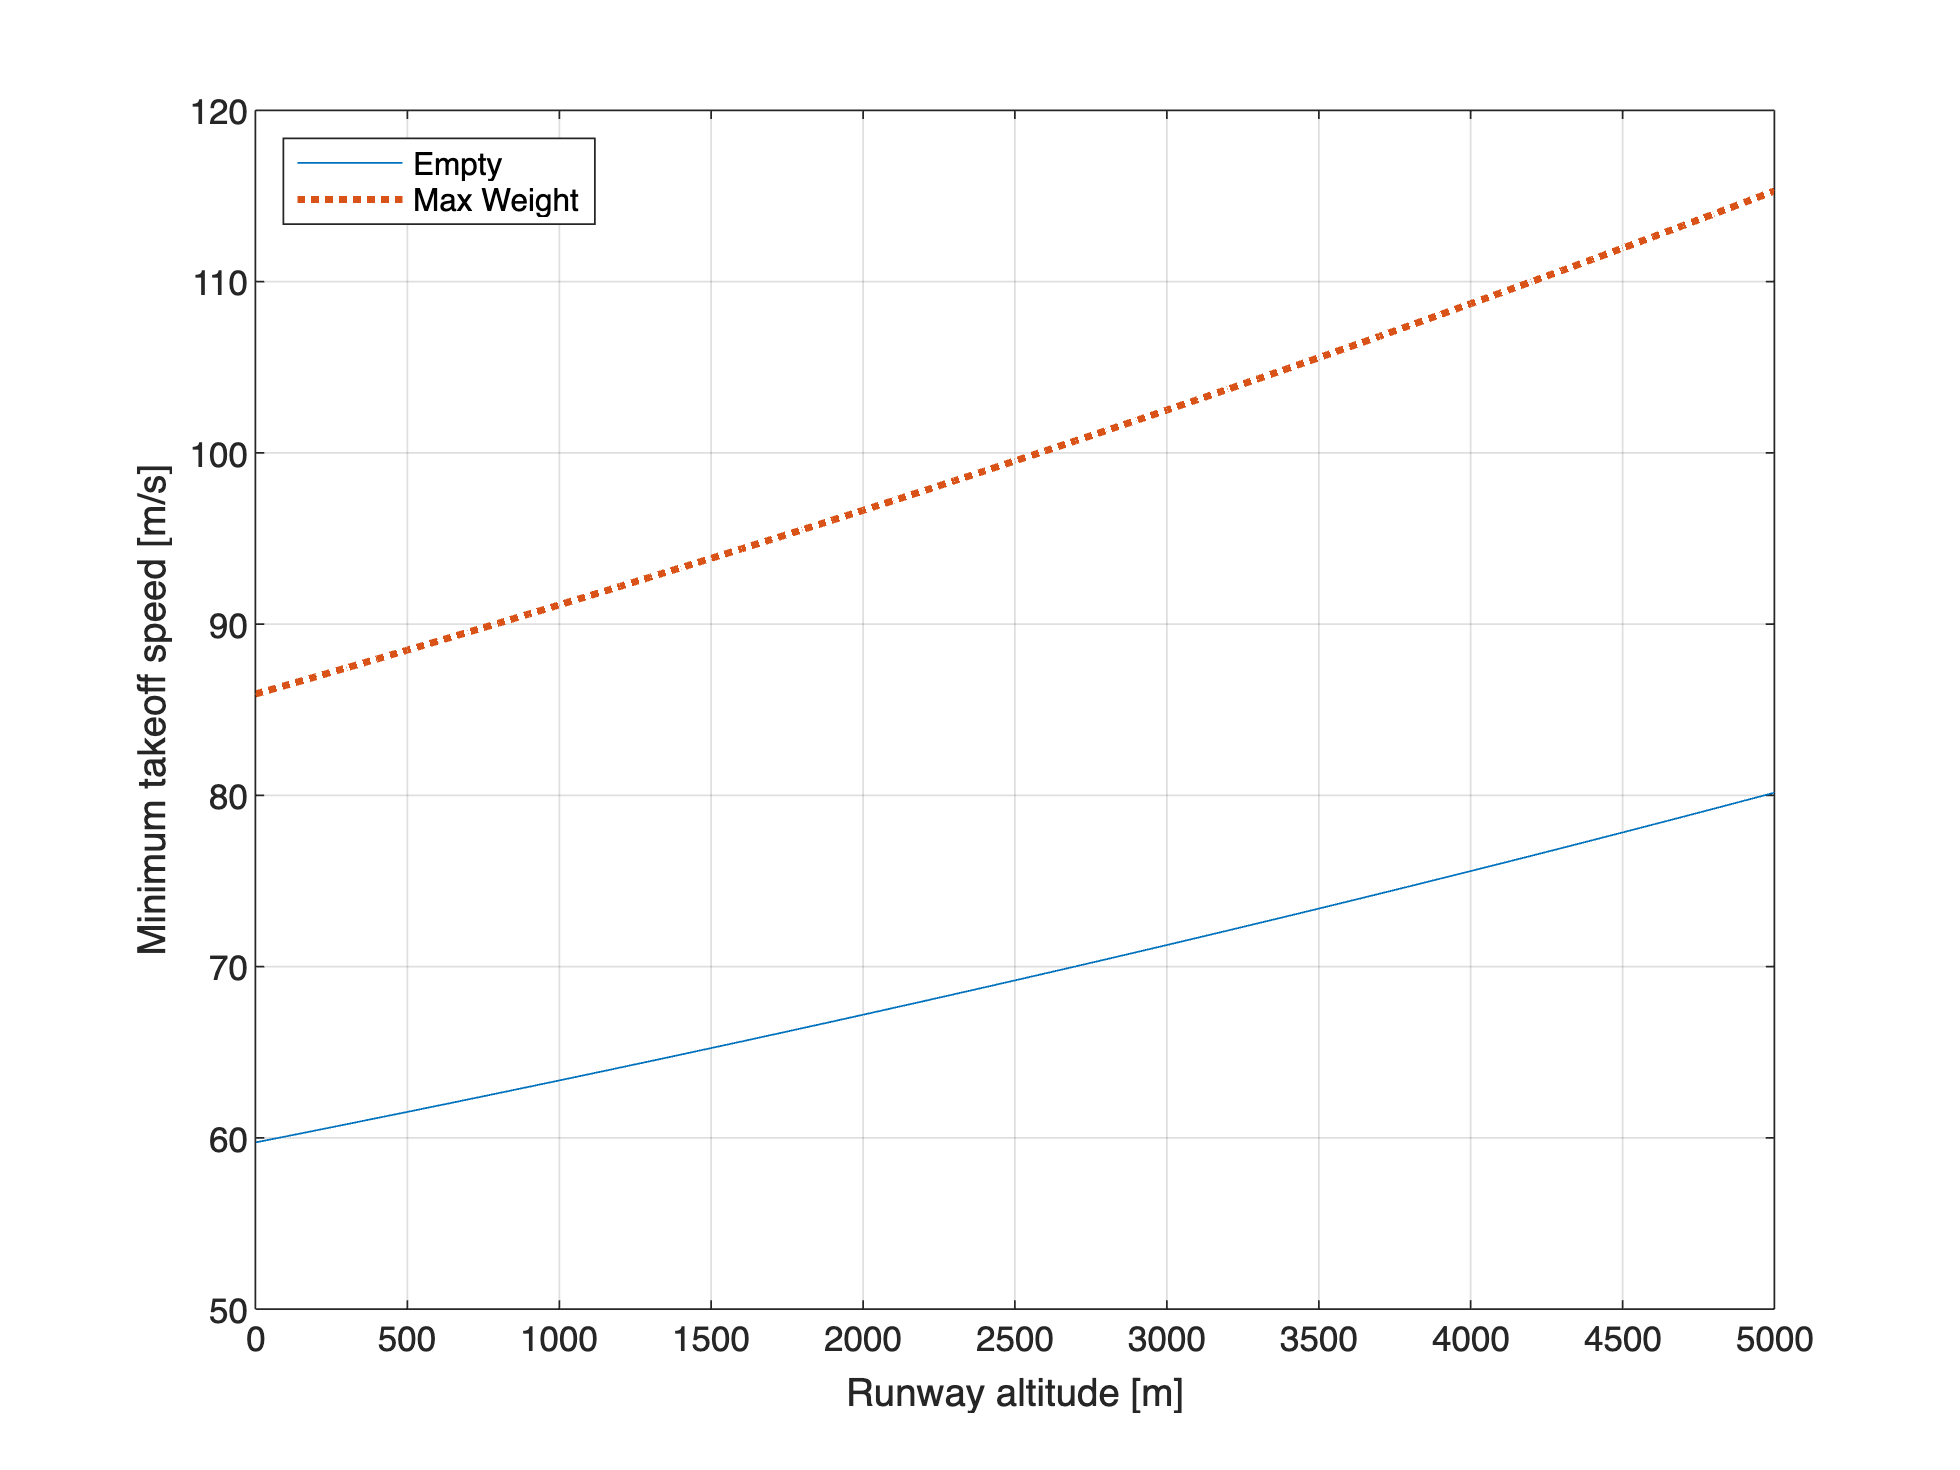

ii = 28

ans = 2700

jj = 9

ans = 800

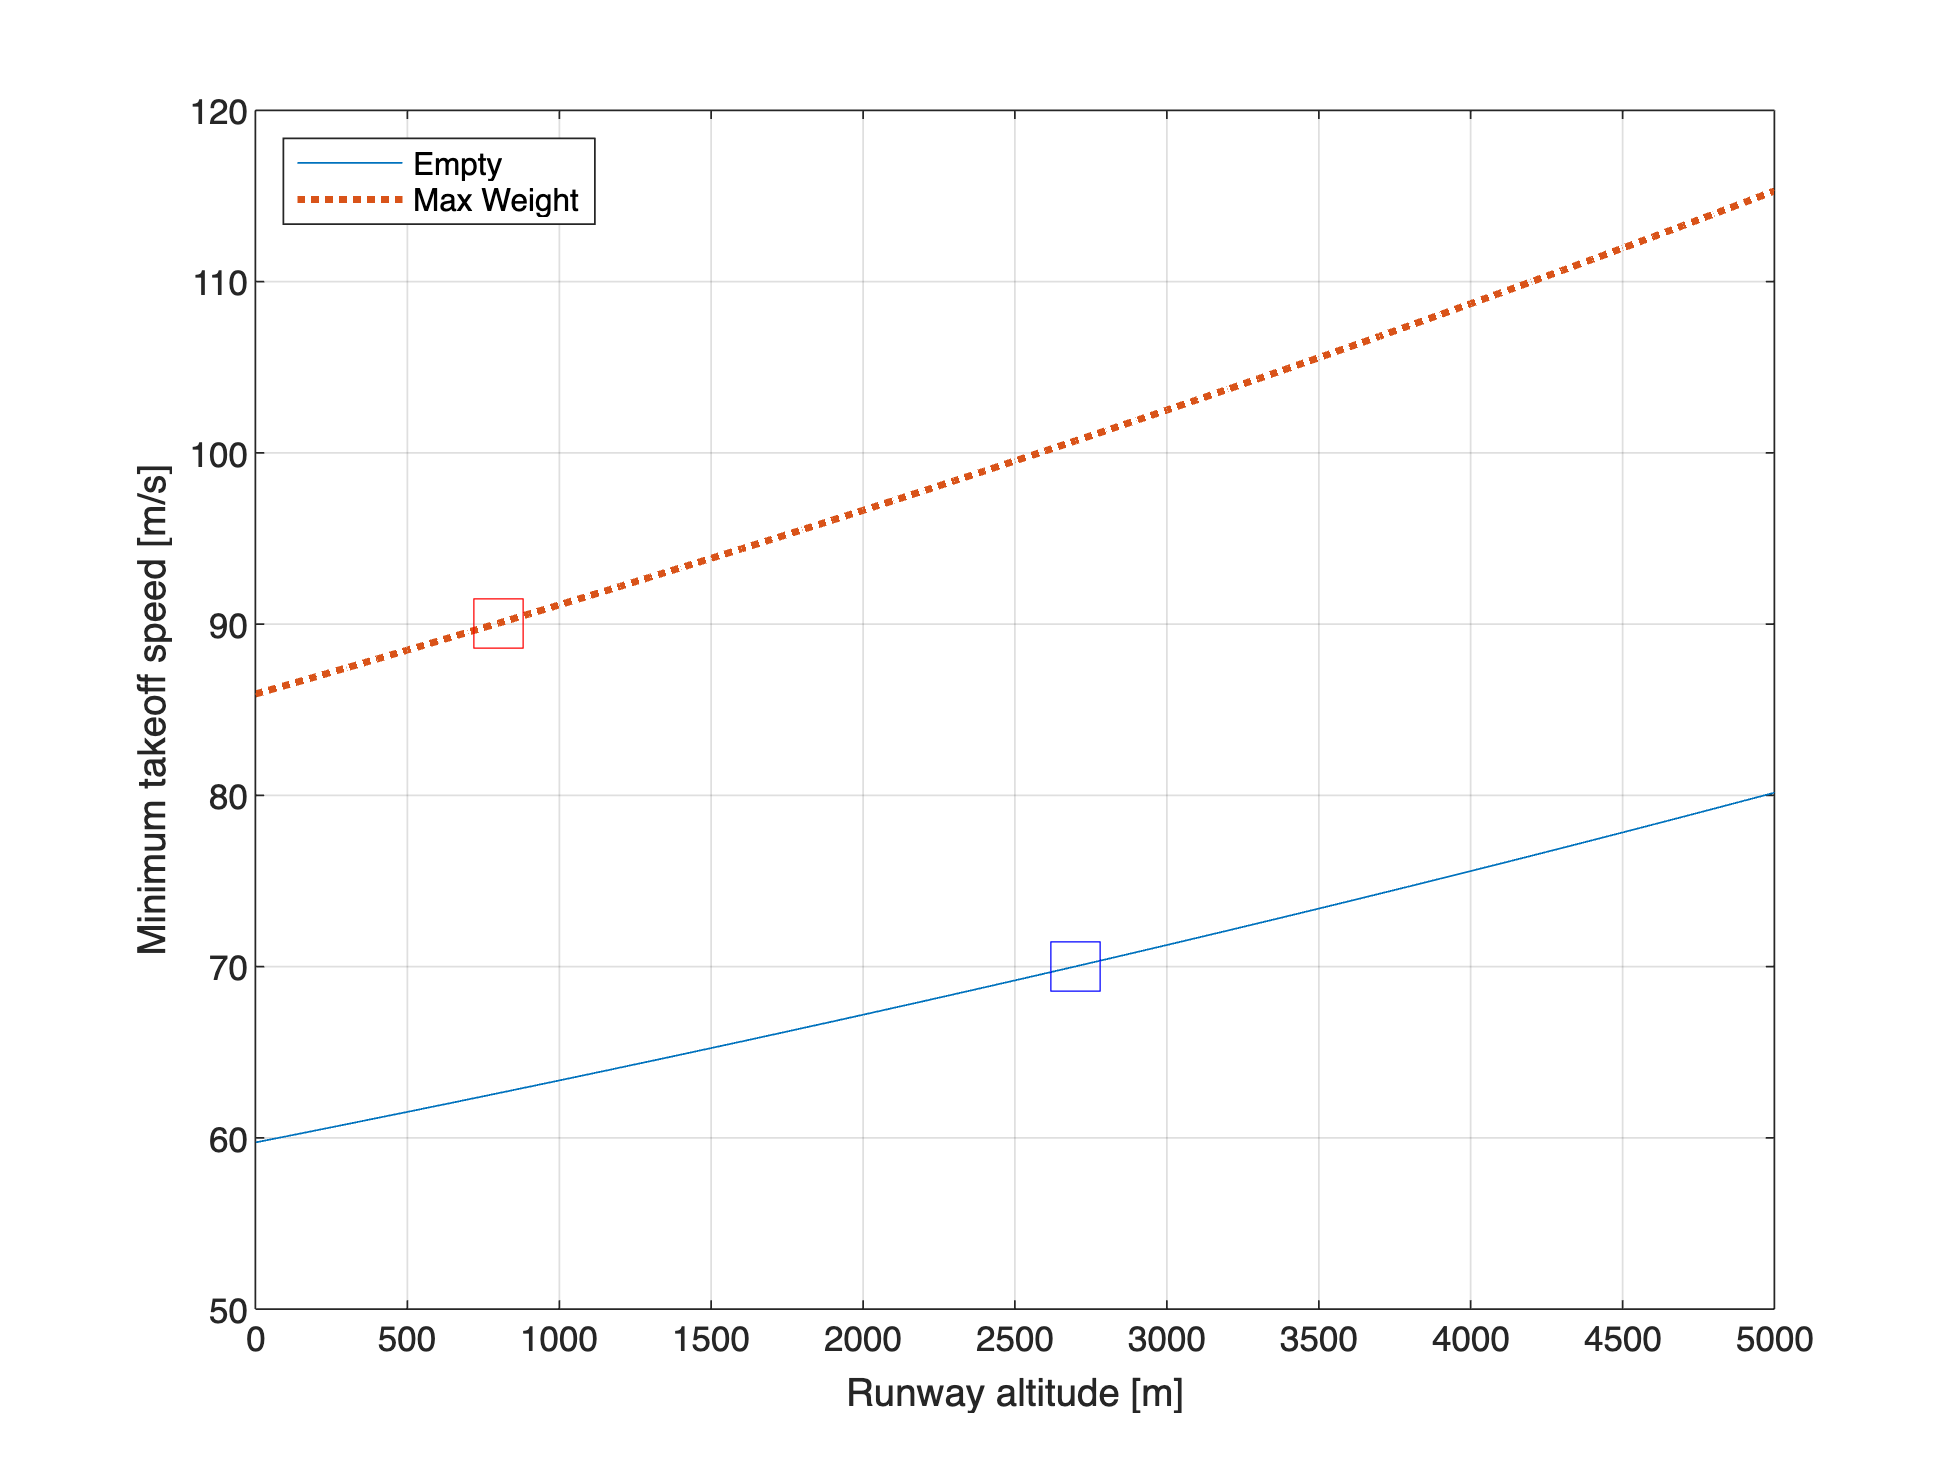

hh =            0        1000        2000        3000        4000        5000


vmin_empty =    59.7276   63.3464   67.1844   71.2550   75.5722   80.1509


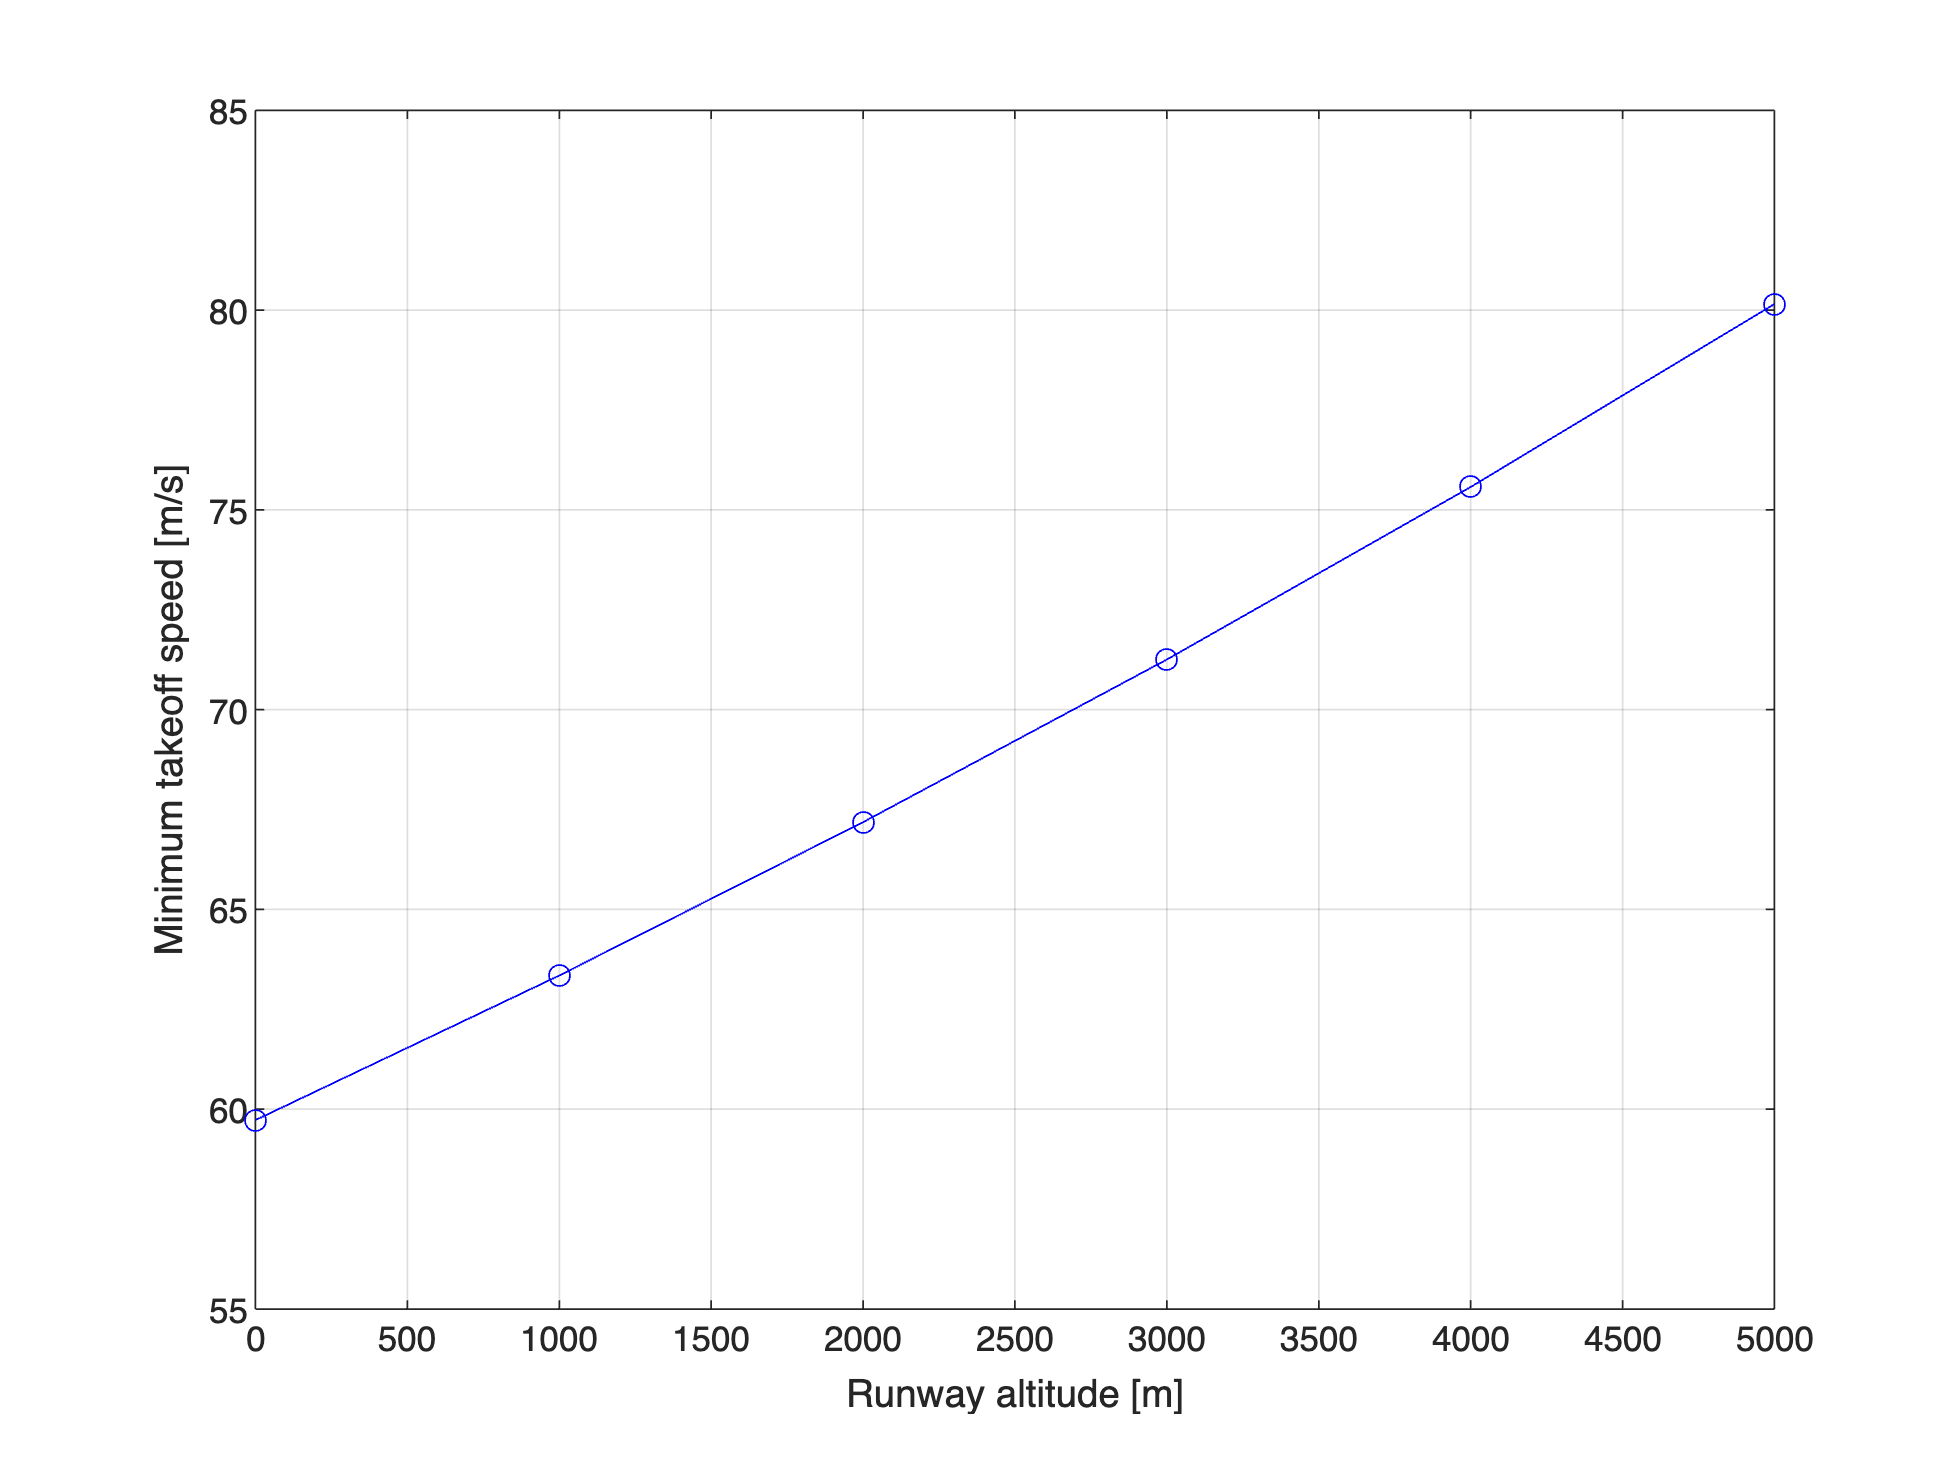

ii =      1     2     3


ans = 67.1844

ans = 2000

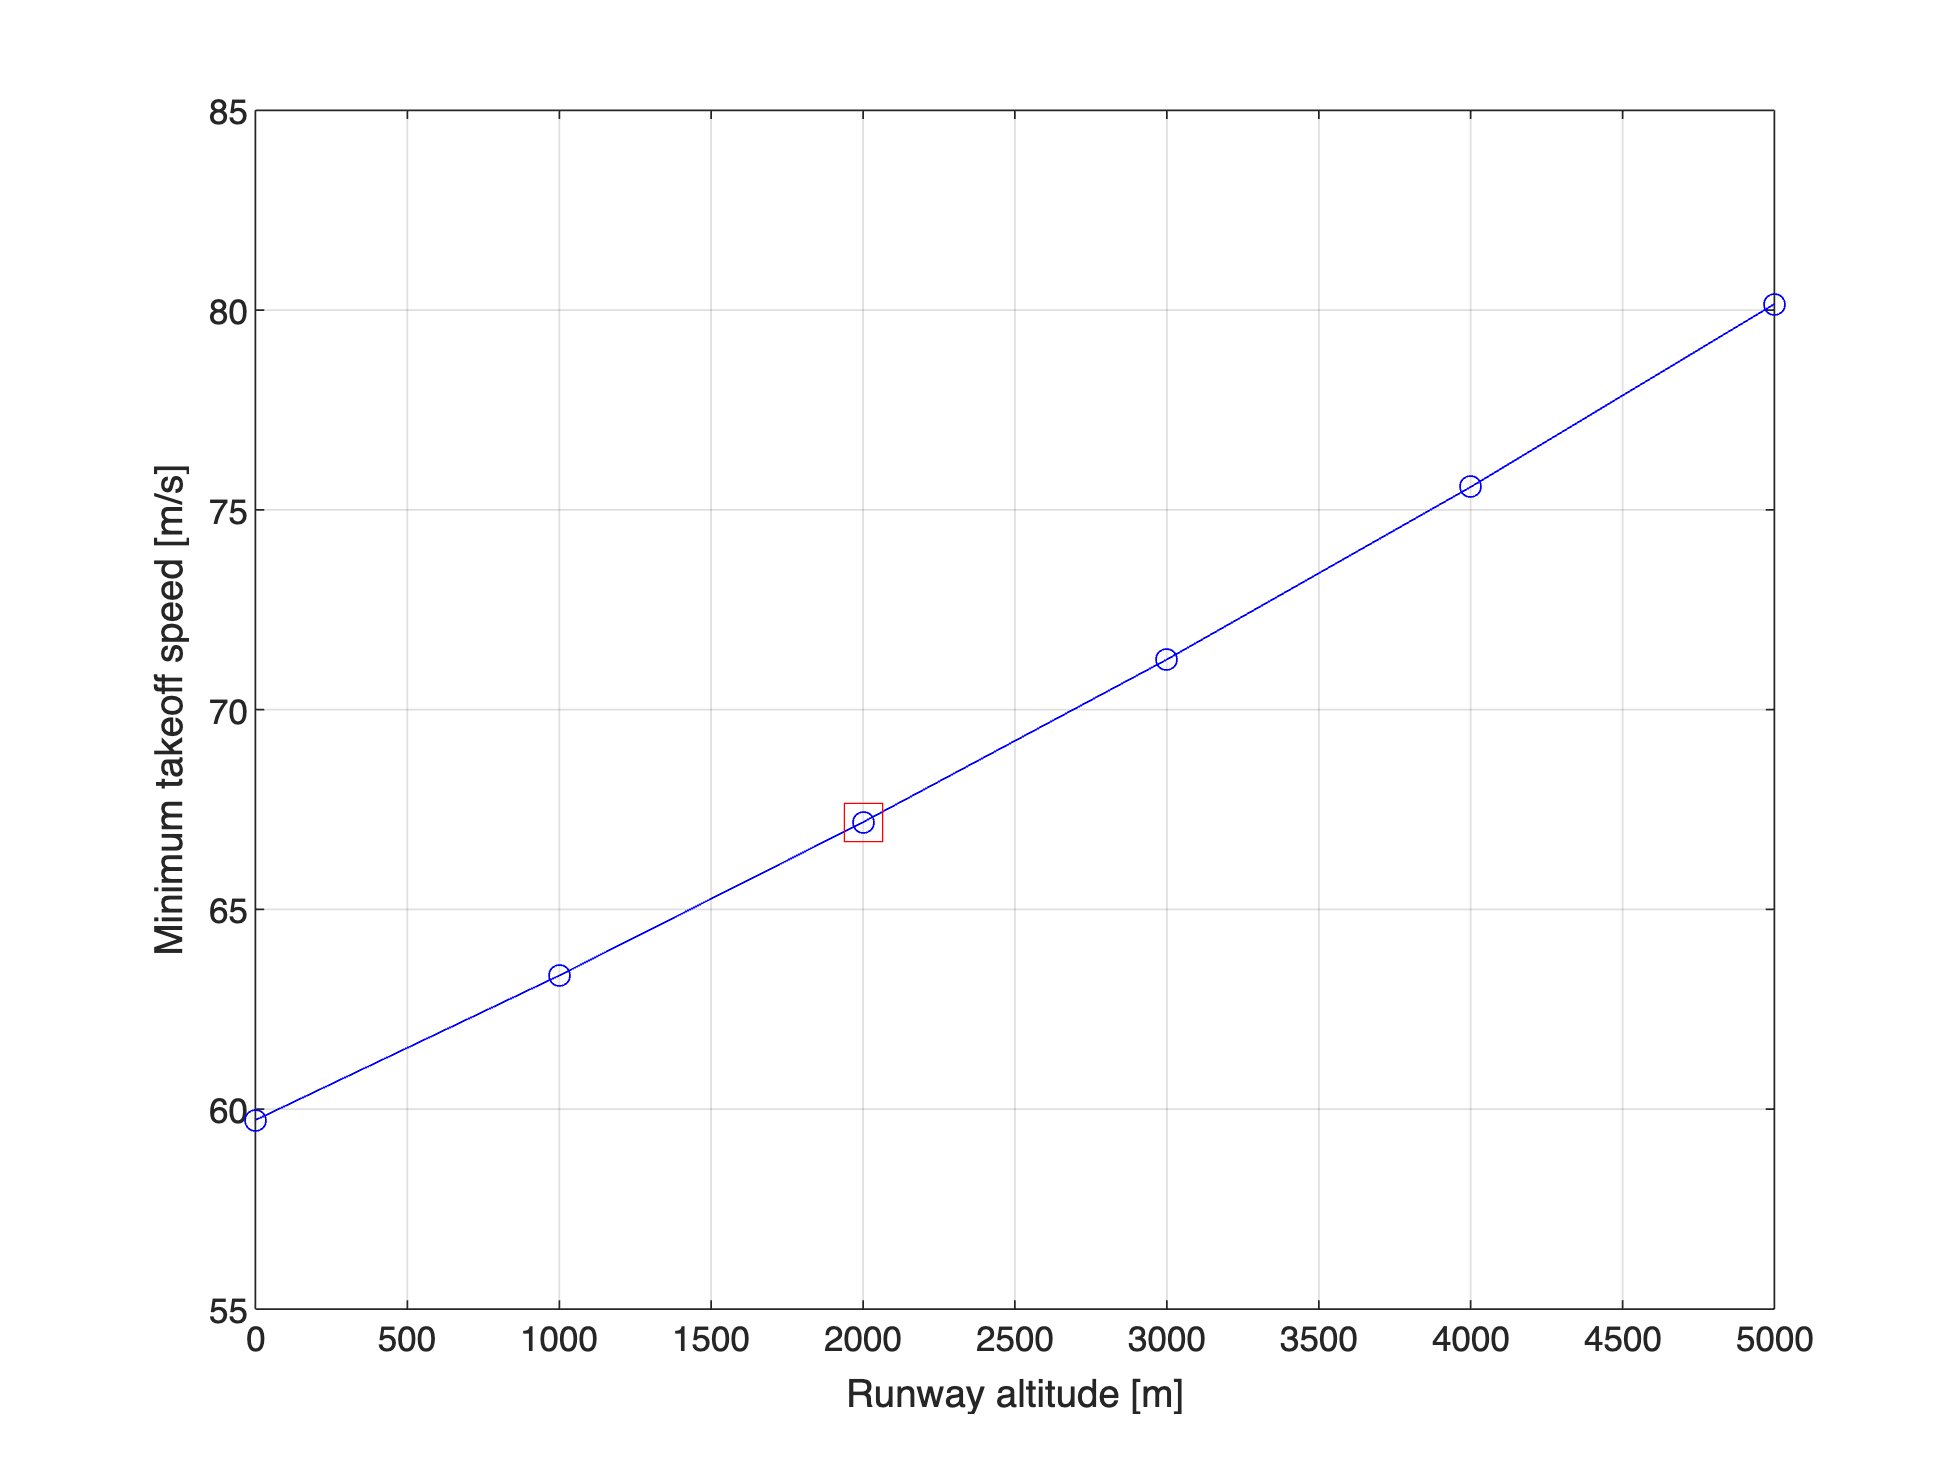

% Your code here.       